clear all;
clf reset;

format longE

Data

ys = (0:0.5:10.0)';
xs = [0; 0.3149803; 0.9999999; 1.9655560; 3.1748020; 4.6050390; 6.2402510;
    8.068264; 10.07937; 12.26556; 14.62009; 17.13712; 19.81156; 22.63891;
    25.61514; 28.73660; 31.99999; 35.40231; 38.94074; 42.61273; 46.41589];

global phi;
phi = @(ys_eval) quadrate_interp(ys_eval, ys, xs);

t0 = 0.5;
y0 = 8;

Try interpolation

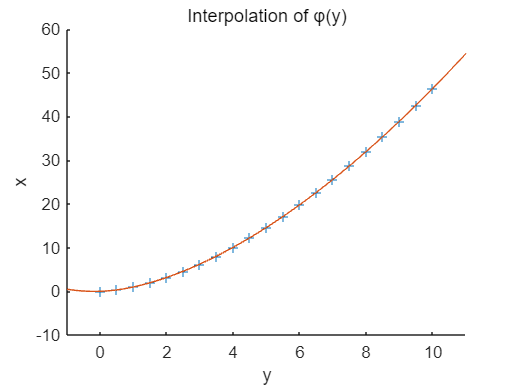

xxs = (-1:0.1:11)';
yys = phi(xxs);
figure;
scatter(ys, xs, 'Marker', '+');
hold on
plot(xxs, yys);
title("Interpolation of φ(y)")
xlabel("y")
ylabel("x")
hold off

Solve for knots

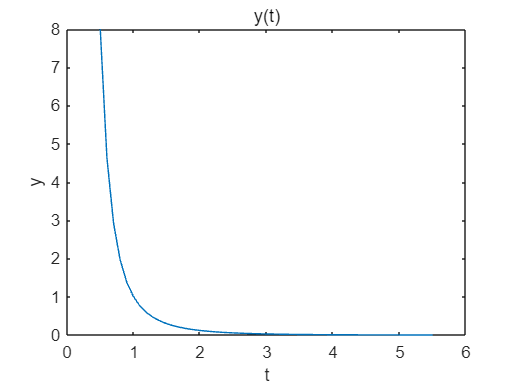

h = 0.1;
t0 = 0.5;
y0 = 8;
n = 51;

[ts, ys] = runge_kutta(@f, t0, y0, h, n);

figure;
plot(ts, ys);
xlabel("t");
ylabel("y");
title("y(t)");


disp("t:")

t:


disp(ts)

     5.000000000000000e-01
     6.000000000000000e-01
     7.000000000000000e-01
     7.999999999999999e-01
     8.999999999999999e-01
     9.999999999999999e-01
     1.100000000000000e+00
     1.200000000000000e+00
     1.300000000000000e+00
     1.400000000000000e+00
     1.500000000000000e+00
     1.600000000000000e+00
     1.700000000000000e+00
     1.800000000000000e+00
     1.900000000000001e+00
     2.000000000000000e+00
     2.100000000000001e+00
     2.200000000000001e+00
     2.300000000000001e+00
     2.400000000000001e+00
     2.500000000000001e+00
     2.600000000000001e+00
     2.700000000000001e+00
     2.800000000000001e+00
     2.900000000000001e+00
     3.000000000000001e+00
     3.100000000000001e+00
     3.200000000000002e+00
     3.300000000000002e+00
     3.400000000000002e+00
     3.500000000000002e+00
     3.600000000000002e+00
     3.700000000000002e+00
     3.800000000000002e+00
     3.900000000000002e+00
     4.000000000000002e+00
     4.100000000000001e+00
 

disp("y:")

y:


disp(ys)

     8.000000000000000e+00
     4.642007938980274e+00
     2.924264866477023e+00
     1.958447844922328e+00
     1.374949009883190e+00
     1.002048161794737e+00
     7.526239539516123e-01
     5.799605239359816e-01
     4.560241803936325e-01
     3.644520760450451e-01
     2.952356936527245e-01
     2.419116519429096e-01
     2.001604196770731e-01
     1.670111193753610e-01
     1.403698430894385e-01
     1.187292579261486e-01
     1.009840543283342e-01
     8.631039375622364e-02
     7.408524757304480e-02
     6.383127010923526e-02
     5.517840446564536e-02
     4.783668527160593e-02
     4.157667607137744e-02
     3.621520140547876e-02
     3.160480781604243e-02
     2.762588823287377e-02
     2.418073336994628e-02
     2.118899401263052e-02
     1.858418771645923e-02
     1.631098654747599e-02
     1.432309447240910e-02
     1.258157386380186e-02
     1.105351692472566e-02
     9.710984077512695e-03
     8.530150494690554e-03
     7.490616031175823e-03
     6.574844268965765e-03
 

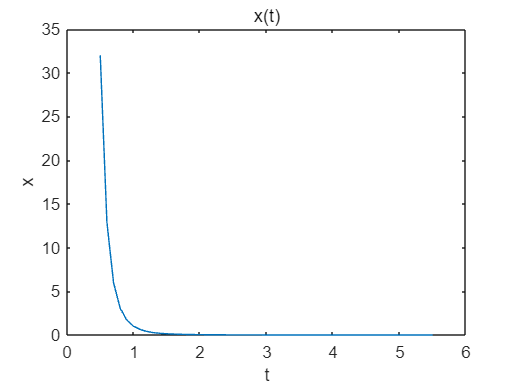


xs = phi(ys);

figure;
plot(ts, xs);
xlabel("t");
ylabel("x");
title("x(t)");


disp("x:")

x:


disp(xs);

     3.199999000000000e+01
     1.291716786333016e+01
     5.980174932185932e+00
     3.065888911044139e+00
     1.701216367617299e+00
     1.003382899770634e+00
     6.260218203356833e-01
     3.996726456708071e-01
     2.724357025990477e-01
     1.930300311059657e-01
     1.412463413569297e-01
     1.061883138640430e-01
     8.167660880455133e-02
     6.405254798612721e-02
     5.106739351508643e-02
     4.129288221273696e-02
     3.379506485489371e-02
     2.794711349013967e-02
     2.331834695773671e-02
     1.960650593010464e-02
     1.659532760696007e-02
     1.412733114642871e-02
     1.208597835860952e-02
     1.038374551768290e-02
     8.954000513542486e-03
     7.745377148338593e-03
     6.717817431576349e-03
     5.839746524547461e-03
     5.086028681427553e-03
     4.436469467889885e-03
     3.874705226259271e-03
     3.387370517449898e-03
     2.963467466953121e-03
     2.593883394636586e-03
     2.271018490906086e-03
     1.988495969926899e-03
     1.740934614552546e-03
 

Composite Simpson (1/3 rule)

sm = 0;

for i = 1 : (n - 1) / 2
    sm = sm + ys(2 * i - 1) + 4 * ys(2 * i) + ys(2 * i + 1);
end

integ = h / 3 * sm;
disp("Integral of y(t) from 0.5 to 5.5:");

Integral of y(t) from 0.5 to 5.5:


disp(integ);

     1.959773240600955e+00



Hence 


$$\int_{0.5}^{5.5}y(t)dt\approx{1.959773240600955}$$


# Functions

RK4

function [ts, ys] = runge_kutta(f, t0, y0, h, n)
    ts = zeros(n, 1);
    ys = zeros(n, 1);
    ts(1) = t0;
    ys(1) = y0;

    ks = zeros(4, 1);
    max_iter = 1000;

    yp0 = f(ts(1), ys(1), 0, max_iter);
    for j = 1 : n - 1
        yp0 = f(ts(j), ys(j), yp0, max_iter);
        ks(1) = h * yp0;
        ks(2) = h * f(ts(j) + 0.5 * h, ys(j) + 0.5 * ks(1), yp0, max_iter);
        ks(3) = h * f(ts(j) + 0.5 * h, ys(j) + 0.5 * ks(2), yp0, max_iter);
        ks(4) = h * f(ts(j) + h, ys(j) + ks(3), yp0, max_iter);

        ys(j + 1) = ys(j) + (ks(1) + 2 * ks(2) + 2 * ks(3) + ks(4)) / 6;
        ts(j + 1) = ts(j) + h;
    end
end

$F(t,y,y')$ and $F_{y'}(t,y,y')$

function val = F(t, y, yp)
    global phi;
    val = yp .^ 3 - 6 * t.^3 .* phi(y) .* y .^ 2 .* yp ...
        + t .^ 3 .* phi(y) .^ 3 + 8 .* t .^ 6 .* y .^ 6;
end

function val = Fypp(t, y, yp)
    global phi;
    val = 3 .* yp .^ 2 - 6 * t.^3 .* phi(y) .* y .^ 2;
end

$y' = f(x,y)$ by Newton's Method

function yp = f(t, y, yp0, max_iter)
    tol = 1e-14;
    yp = 100000; % inf
    i = 0;

    % Newton's Method
    while true
        if i > max_iter
            disp("Not converge. " + yp0);
            break;
        end

        yp = yp0 - F(t, y, yp0) / Fypp(t, y, yp0);
        if abs(yp - yp0) / abs(yp) <= tol
            break;
        end
        yp0 = yp;
    end
end

Quadrate Interpolation

function ys_evel = quadrate_interp(xs_evel, xs, ys)
    n = length(xs);

    x_bond = zeros(1, n - 1); 
    x_bond(1) = min(xs);
    for i = 2 : n - 2
        x_bond(i) = 0.5 * (xs(i) + xs(i + 1));
    end
    x_bond(end) = max(xs);
    
    count = 1;
    ys_evel = zeros(length(xs_evel), 1);
    for x = xs_evel'
        for j = 1 : length(x_bond)
            if x < x_bond(j)
                i = j - 1;
                break;
            end
        end
    
        if i == 0
            i = 1;
        elseif i > length(xs)
            i = length(xs);
        end

        x0 = xs(i); x1 = xs(i + 1); x2 = xs(i + 2);
        y0 = ys(i); y1 = ys(i + 1); y2 = ys(i + 2);
    
        ys_evel(count) ...
            = y0 * (x - x1) * (x - x2) / (x0 - x1) / (x0 - x2) ...
            + y1 * (x - x0) * (x - x2) / (x1 - x0) / (x1 - x2) ...
            + y2 * (x - x0) * (x - x1) / (x2 - x0) / (x2 - x1);
        count = count + 1;
    end
end